% MATLAB Homework 2_Fall2023

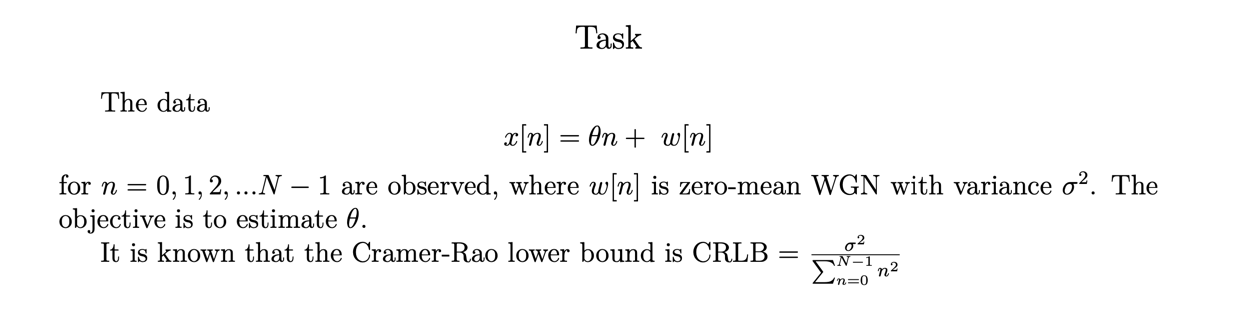

% Setting up parameters of Monte Carlo simulation
% ---------------------------------------
clc
clear all
clf

numMonteCLoops = 1E4; % Number of Monte Carlo Loops
N = 1; % Number of observations
noise_var = 2; % Variance of WGN
theta = 10; % True value of the parameter
% ---------------------------------------

% Initializing variable for stability
estimate = ones(1,numMonteCLoops)*NaN;

for MC=1:numMonteCLoops
    %%% defining the Numerator in the estimator equation
    % x[n]*n = theta*n*n + n*w[n]
    noisePart = randn(1,N)*sqrt(noise_var).*(1:N); % the WGN part
    numSignal = theta*(1:N).^2 + noisePart; % the signal parr

    %% defining the denominator in the estimator equation
    denomSignal = (1:N).^2;

    %% defining the estimate as the divisions of summations of numerator
    %% and denominator
    estimate(MC) = sum(numSignal) / sum(denomSignal);    
end

%% Checking whether the mean of the estimate is closely approximated to the 
%% true value of the parameter
fprintf('Expected value of the estimate is: %s\n', num2str(mean(estimate)));

Expected value of the estimate is: 10.0131


if round(mean(estimate))== theta
    disp("The estimator is performing unbiased")
end

The estimator is performing unbiased



%% Calculating the CRLB for simulation
CRLB_theta = (noise_var) / (sum((1:N).^2));

%% Check whether CRLB simulated value and the variance simulated value 
%% are approximately the same or not.
fprintf('Cramer-Rao Lower Bound is : %s\n', num2str(CRLB_theta));

Cramer-Rao Lower Bound is : 2


fprintf('Variance of the estimate is: %s\n', num2str(var(estimate)));

Variance of the estimate is: 1.9696



if abs(round(var(estimate),3) - round(CRLB_theta,3))== 0
    disp("The estimator is performing efficient")
end

% Initiating figure
figure(1)
clf
% Drawing the Probability Density Function of the simulated estimates
H = histogram(estimate, 'Normalization', 'pdf');
hold on

% Taking a copy of x values for the theoritical PDF
x = linspace(H.BinLimits(1),H.BinLimits(2),100);

%% Calculation of theoritical mean and variance included in the report
theo_mean = theta;
CRLB = noise_var/ (N*(N+1)*((2*N)+1)/6);
theo_var = CRLB

theo_var = 2

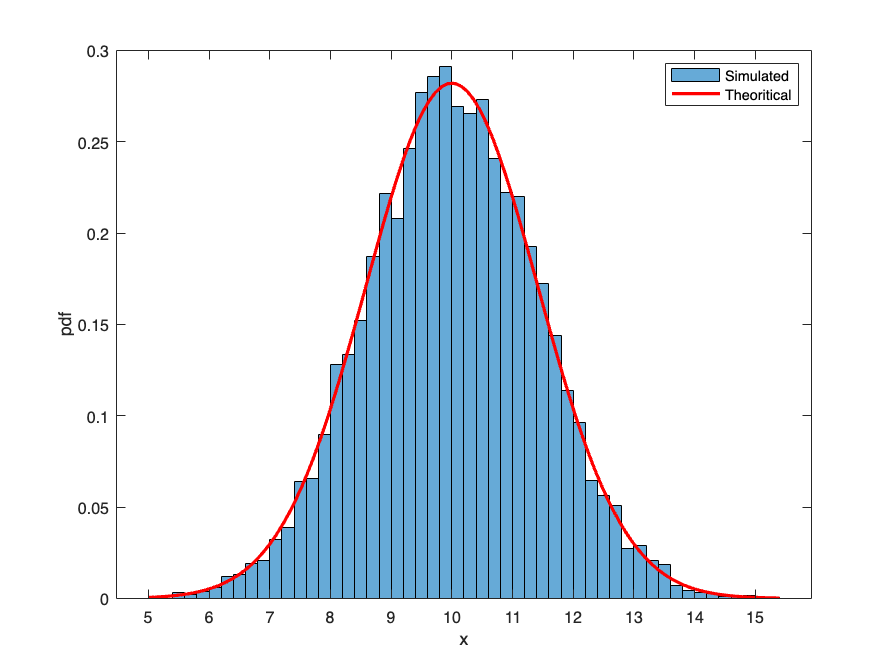


%% Defining the Theoritical PDF using theoritical mean and variance
theo_pdf = 1 / (sqrt(2 * pi * theo_var)) * exp(-((x - theo_mean).^2) / (2 * theo_var));

%% Ploting the Theoritical PDF on top of the PDF of simulated values
plot(x, theo_pdf, 'r', 'LineWidth', 2);
legend('Simulated','Theoritical');
xlabel('x');
ylabel('pdf')

'estimate' requires Econometrics Toolbox.